# Rocker State Estimator

Authors: Daniel J. Pearson & Colette B. Scott

Version: 1/12/2024

clear variables; close all; clc;

## EKF Initialization

% Initialize initial state
x = [0;1;0;0;0;0;0;0;0;0];
x_min = [0;1;0;0;0;0;0;0;0;0];

P = eye(10); % Error Covariance
P_min = eye(10); 

% Sensor Variance
% gyroVariance = 0.00637; % [Rad/s]
% accelVariance = 0.00069 * sqrt(40); % [m/s/s]
% magVariance = 0.008; % [nT]
accelXYVariance = 0.00637; % [m/s^2]
accelZVariance = 0.00686; % [m/s^2]
gyroVariance = 0.000489; % [rad/s]
magVariance = 120; % [nT]

% Sensor Noise Covariance
R = diag([accelVariance^2,accelVariance^2,accelVariance^2,magVariance^2,magVariance^2,magVariance^2]);

gyroAccelVar = diag([gyroVariance^2, gyroVariance^2, gyroVariance^2, accelVariance^2, accelVariance^2, accelVariance^2]);

dt = 1/400; %[s] 400Hz

## Rocket & Global Constants

% Earth Constants
rho = 1.22; % [kg/m^3] Air Density
g = 9.81; % [m/s/s] Gravitational Acceleration

% Rocket Constants
S_r = (pi/4)*0.152^2;
C_d = 0.4;
m = 1; % [kg]

## Magnetometer Calibration

magCalVector = [133160; 131450; 133030];

## Data Loading

csvLog = readtable('./data/PayloadDropTest.csv');

## Estimation Loop

x_storage = zeros(length(csvLog.Timestamp), numel(x));

for i = 1:size(csvLog)
    accelX = csvLog.AccelX(i) * 9.81; % [m/s^2]
    accelY = csvLog.AccelY(i) * 9.81; % [m/s^2]
    accelZ = csvLog.AccelZ(i) * 9.81; % [m/s^2]

    gyroX = csvLog.GyroX(i) * (pi/180); % [rad/s]
    gyroY = csvLog.GyroY(i) * (pi/180); % [rad/s]
    gyroZ = csvLog.GyroZ(i) * (pi/180); % [rad/s]

    magX = 8 * ((csvLog.MagX(i) - magCalVector(1)) / magCalVector(1)); % [G]
    magY = 8 * ((csvLog.MagY(i) - magCalVector(2)) / magCalVector(2)); % [G]
    magZ = 8 * ((csvLog.MagZ(i) - magCalVector(3)) / magCalVector(3)); % [G]

    magX = magX * 100000;
    magY = magY * 100000;
    magZ = magZ * 100000;

    u = [gyroX; gyroY; gyroZ; accelX; accelY; accelZ];

    x_min = measurementFunction(x,u,dt);

    A = measurementJacobian(u, dt);

    W = gyroNoisePropagation(x,dt);

    Q = W * gyroAccelVar * W';

    P_min = A*P*A' + Q;

    magVector = [magX; magY; magZ];
    magVector = magVector / norm(magVector);

    accelVector = [accelX; accelY; accelZ];
    accelVector = accelVector / norm(accelVector);

    z = [accelVector; magVector];

    h = updateFunction(x_min);
    H = updateJacobian(x_min);

    v = z - h;
    S = H*P_min*H' + R;
    K = P_min*H' / S;

    x = x_min + K*v;

    x(2:4) = x(2:4) / norm(x(2:4));

    P = (eye(10) - K*H)*P_min;

    x_storage(i, :) = x;
end

### Plotting

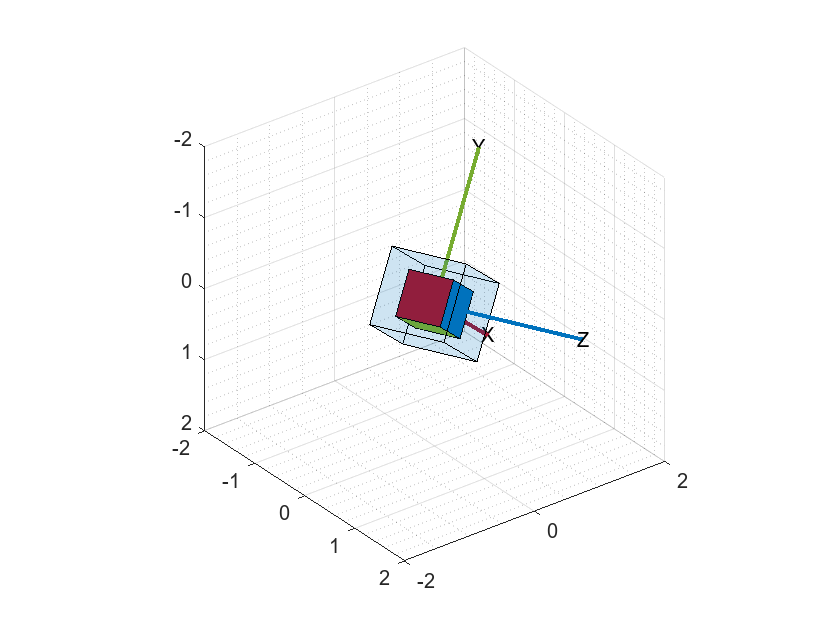

time = csvLog.Timestamp / 1000;

figure();
quatPlot = poseplot();

for i = 1:length(time)

    % q = x_storage(i, 1:4);
    q = [csvLog.Q(i), csvLog.I(i), csvLog.J(i), csvLog.K(i)];

    % q = quaternion(q);
    q = quaternion(x_storage(i,1), x_storage(i,2), x_storage(i,3), x_storage(i,4));

    % rot = quat2rotm(q);

    set(quatPlot, Orientation=q, Position=[0,0,0]);

    % set(quatPlot, 'XData', 0, 'YData', 0, 'ZData', 0, 'Matrix', rot);
    
    drawnow;

    pause(1/400);
end

function f = measurementFunction(x,u,dt)
    quat = x(1:4);

    p = u(1); q = u(2); r = u(3);

    dq = [
        quat(1) - (dt/2)*p*quat(2) - (dt/2)*q*quat(3) - (dt/2)*r*quat(4);
        quat(2) + (dt/2)*p*quat(1) - (dt/2)*q*quat(4) + (dt/2)*r*quat(3);
        quat(3) + (dt/2)*p*quat(4) + (dt/2)*q*quat(1) - (dt/2)*r*quat(2);
        quat(4) - (dt/2)*p*quat(3) + (dt/2)*q*quat(2) + (dt/2)*r*quat(1)    
    ];

    dq(2:4) = dq(2:4) / norm(dq(2:4));

    dv = [0;0;0];
    
    dp = [0;0;0];

    f = [dq; dv; dp];
end

function A = measurementJacobian(u,dt)
    p = u(1); q = u(2); r = u(3);

    A = [
        1, (-dt/2)*p, (-dt/2)*q, (-dt/2)*r, 0, 0, 0, 0, 0, 0;
        (dt/2)*p, 1, (dt/2)*r, (-dt/2)*q, 0, 0, 0, 0, 0, 0;
        (dt/2)*q, (-dt/2)*r, 1, (dt/2)*p, 0, 0, 0, 0, 0, 0;
        (dt/2)*r, (dt/2)*q, (-dt/2)*p, 1, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0, 0, 0;
    ];

end

function h = updateFunction(x)
    magneticDip = deg2rad(66.546);

    % NED magnetic vector
    r = [cos(magneticDip); 0; sin(magneticDip)];
    r = r / norm(r);

    % NED Gravity Vector
    G = [0; 0; -9.81];
    G = G / norm(G);

    q = x(1:4);
    q = q / norm(q);

    rotm = quat2rotm(q');

    a_hat = rotm'*G;
    m_hat = rotm'*r;

    h = [
        a_hat;
        m_hat;
    ];
end

function H = updateJacobian(x)
    magneticDip = deg2rad(66.546);

    % NED magnetic vector
    r = [cos(magneticDip); 0; sin(magneticDip)];
    r = r / norm(r);

    % NED Gravity Vector
    G = [0; 0; -9.81];
    G = G / norm(G);

    q = x(1:4);
    q = q / norm(q);

    rx = r(1);
    ry = r(2);
    rz = r(3);
    gx = G(1);
    gy = G(2);
    gz = G(3);

    qw = q(1);
    qx = q(2);
    qy = q(3);
    qz = q(4);

    H = [
        gx*qw+gy*qz-gz*qy, gx*qx+gy*qy+gz*qz, -gx*qy+gy*qx-gz*qw, -gx*qz+gy*qw+gz*qx, 0, 0, 0, 0, 0, 0;
        -gx*qz+gy*qw+gz*qx, gx*qy-gy*qx+gz*qw, gx*qx+gy*qy+gz*qz, -gx*qw-gy*qz+gz*qy, 0, 0, 0, 0, 0, 0;
        gx*qy-gy*qx+gz*qw, gx*qz-gy*qw-gz*qx, gx*qw+gy*qz-gz*qy, gx*qx+gy*qy+gz*qz, 0, 0, 0, 0, 0, 0;
        rx*qw+ry*qz-rz*qy, rx*qy+ry*qy+rz*qz, -rx*qy+ry*qx-rz*qw, -rx*qz+ry*qw+rz*qx, 0, 0, 0, 0, 0, 0;
        -rx*qz+ry*qw+rz*qx, rx*qy-ry*qx+rz*qw, rx*qx+ry*qy+rz*qz, -rx*qw-ry*qz+rz*qy, 0, 0, 0, 0, 0, 0;
        rx*qy-ry*qx+rz*qw, rx*qz-ry*qw-rz*qx, rx*qw+ry*qz-rz*qy, rx*qx+ry*qy+rz*qz, 0, 0, 0, 0, 0, 0;
        
        ];
end

function W = gyroNoisePropagation(x,dt)
    W = [
        -0.5*x(2), -0.5*x(3), -0.5*x(4), 0, 0, 0;
        0.5*x(1), -0.5*x(4), 0.5*x(3), 0, 0, 0;
        0.5*x(4), 0.5*x(1), -0.5*x(2), 0, 0, 0;
        -0.5*x(3), 0.5*x(2), 0.5*x(1), 0, 0, 0;
        0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0;
    ];
end